load('C:\Users\mehul\Documents\PhD\REPOS_ONLINE\BMH_utils_matlab\DATA\fsLR_32k_facesAndVerts.mat')
cortexMask = logical(readmatrix('C:\Users\mehul\Documents\PhD\REPOS_ONLINE\BrainEigenmodes\data\template_surfaces_volumes\fsLR_32k_cortex-lh_mask.txt'));
% dataModes = readmatrix('james-code_sphere_emodes_yeo_noMask.txt');
dataModes = readmatrix('C:\Users\mehul\Documents\PhD\REPOS_ONLINE\BrainEigenmodes\data\examples\fsLR_32k_midthickness-lh_emode_50.txt');



dataModes = dataModes(:,1:49);
% dataModes = [dataModes, zeros(size(dataModes, 1), 5)];

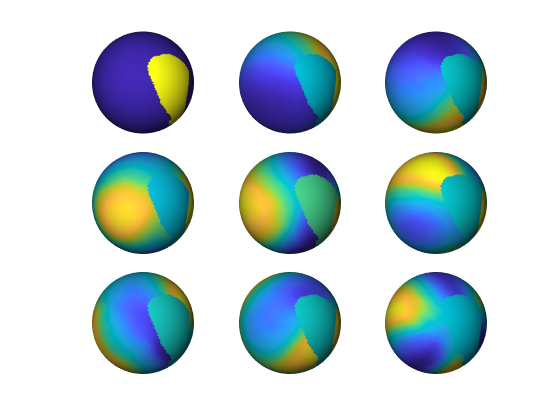


figure; 
plotBrain(lh_verts_sphere, lh_faces, [], dataModes(:, 1:9));

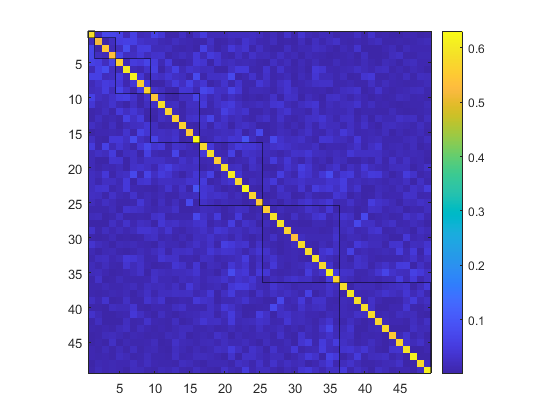


figure; 
imagescmode(abs(dataModes.' * dataModes));

% 
% dataModes2 = dataModes;
% 
% for ii = 2:5
%     rot = makeRandomRotationMatrix(2*ii-1);
%     dataModes2(:, getEigengroupIdx(ii)) = dataModes(:, getEigengroupIdx(ii))*rot';
% end
% 
% figure; 
% plotBrain(lh_verts_sphere, lh_faces, ones(length(lh_verts_sphere),1), dataModes2);
% 
% 
% figure; 
% imagesc(dataModes2.' * dataModes2);


tic;
dataModes3 = eigenstrap(dataModes);
toc;

Elapsed time is 0.048614 seconds.


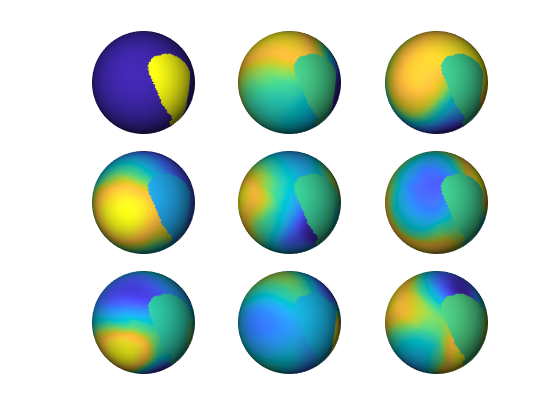


figure; 
plotBrain(lh_verts_sphere, lh_faces, [], dataModes3(:,1:9));

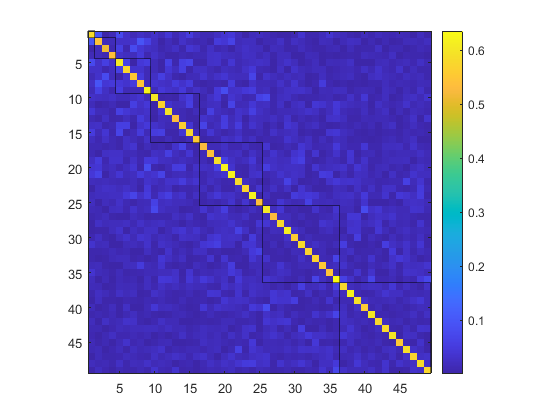



figure; 
imagescmode(abs(dataModes3.' * dataModes3));

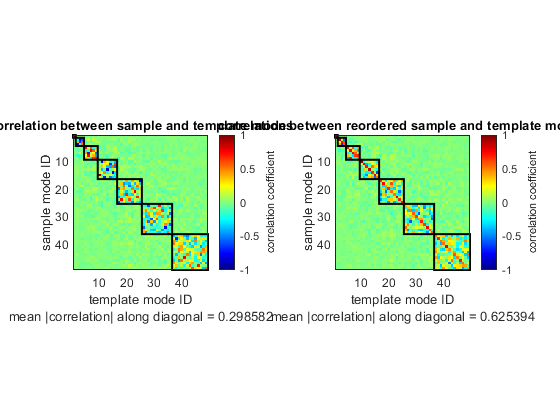


matchModes(dataModes3, dataModes, 'showFigures', 1);

% [vertsMasked, facesMasked] = trimExcludedRois(lh_verts_sphere, lh_faces, cortexMask);
% dataModesMasked = dataModes(cortexMask,:);

tic;
dataModes4 = eigenstrap(dataModes, cortexMask);
toc;

Elapsed time is 0.035036 seconds.


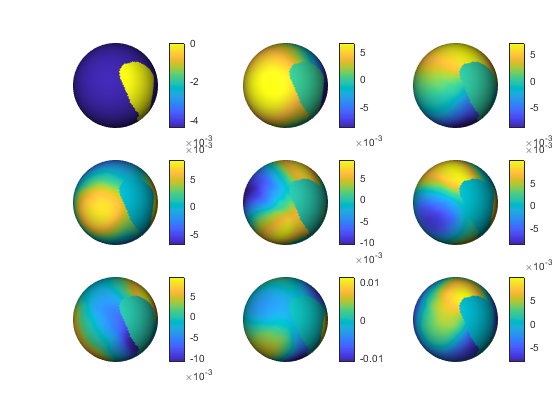


figure; 
plotBrain('lh', {lh_verts_sphere, lh_faces, [], dataModes4(:,1:9)}, 'view', 'lm', 'colorbarOn', true);

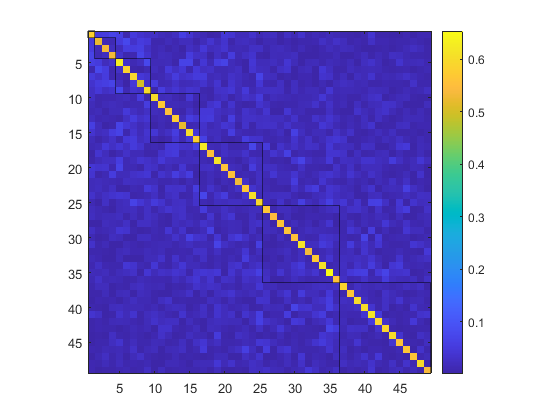

% plotBrain('lh', {vertsMasked, facesMasked, ones(length(vertsMasked),1), dataModes4(:,1:9)}, 'view', 'lm');


% figure; 
% imagescmode(abs(dataModes.' * dataModes));
% 
% figure; 
% imagescmode(abs(dataModes(cortexMask,:).' * dataModes(cortexMask,:)));


figure; 
imagescmode(abs(dataModes4.' * dataModes4));

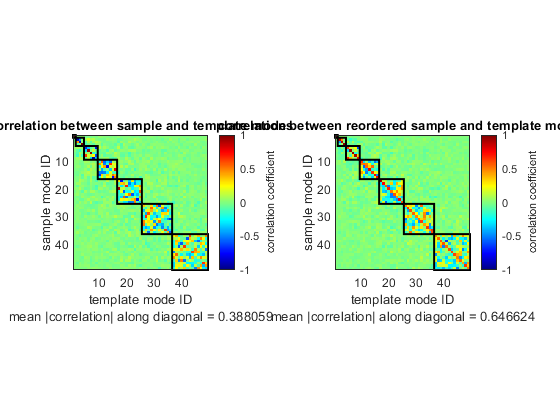


matchModes(dataModes4, dataModes, 'showFigures', 1);